# How to draw a bifurcation diagram

Modifies the example `continuationInstructions.mlx` to include a cubic-quintic nonlinearity such that the sign is flipped on the cubic term. This leads to branches that head to the right before turning left.

## Construct the quantum graph and find the first few eigenfunctions

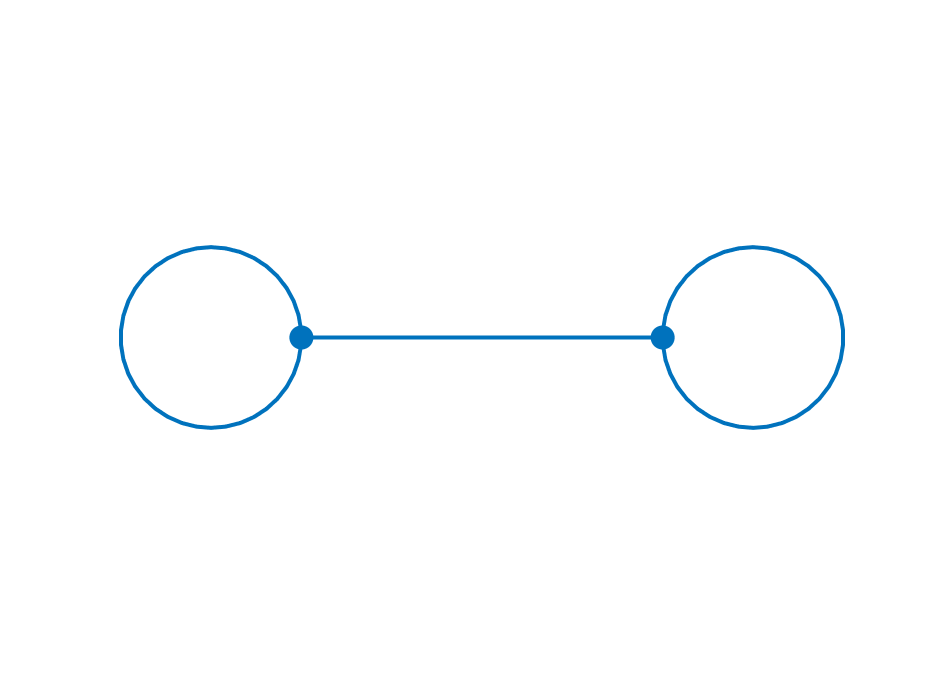

Created directory data/dumbbell/114.
Run number is 114.


tag='dumbbell';
L = [2*pi 4 2*pi];
nxvec=6;
Phi=quantumGraphFromTemplate(tag,'LVec',L,'nX',nxvec,'discretization','Uniform');
dataDir = makeContinuationDirectory(Phi,tag);

#### Compute and save some eigenfunctions

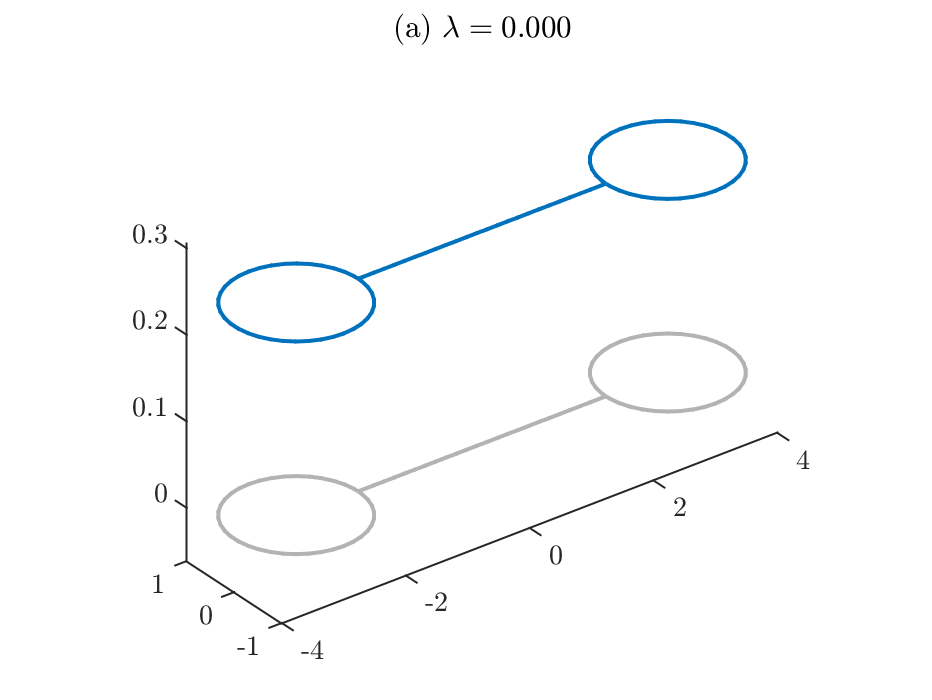

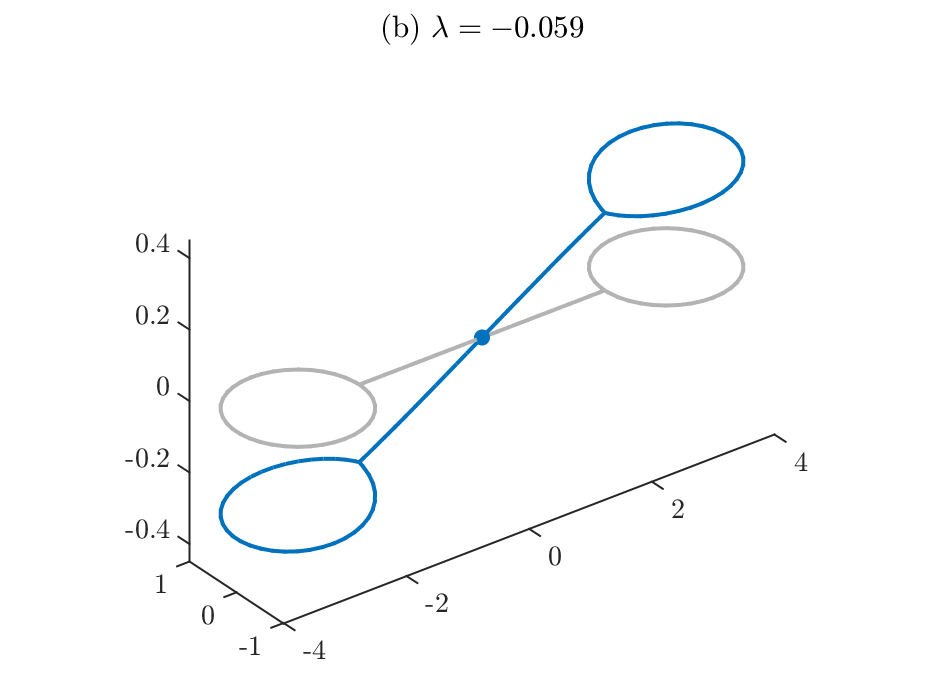

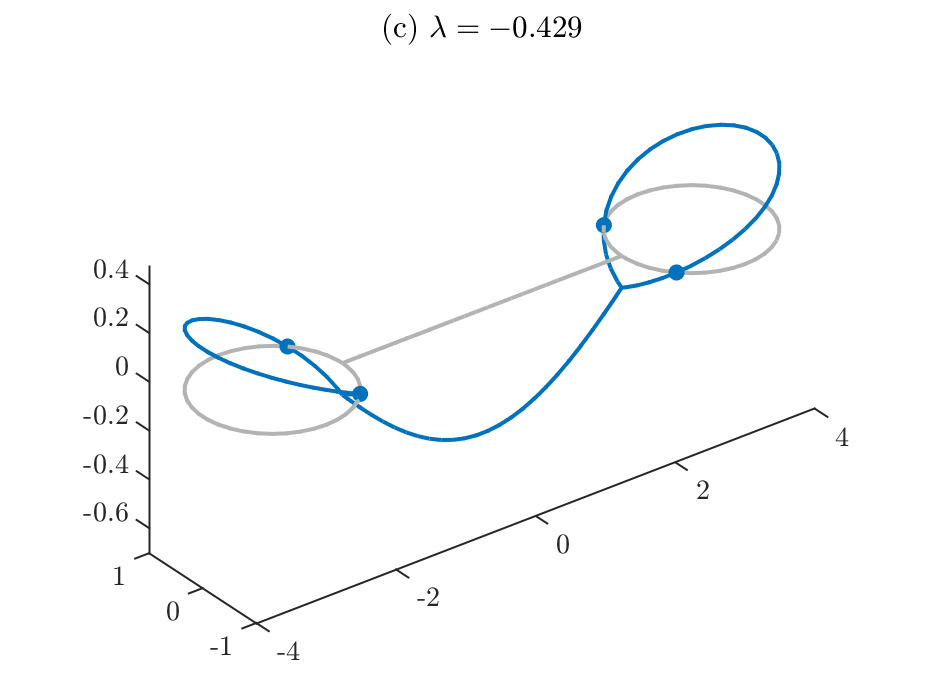

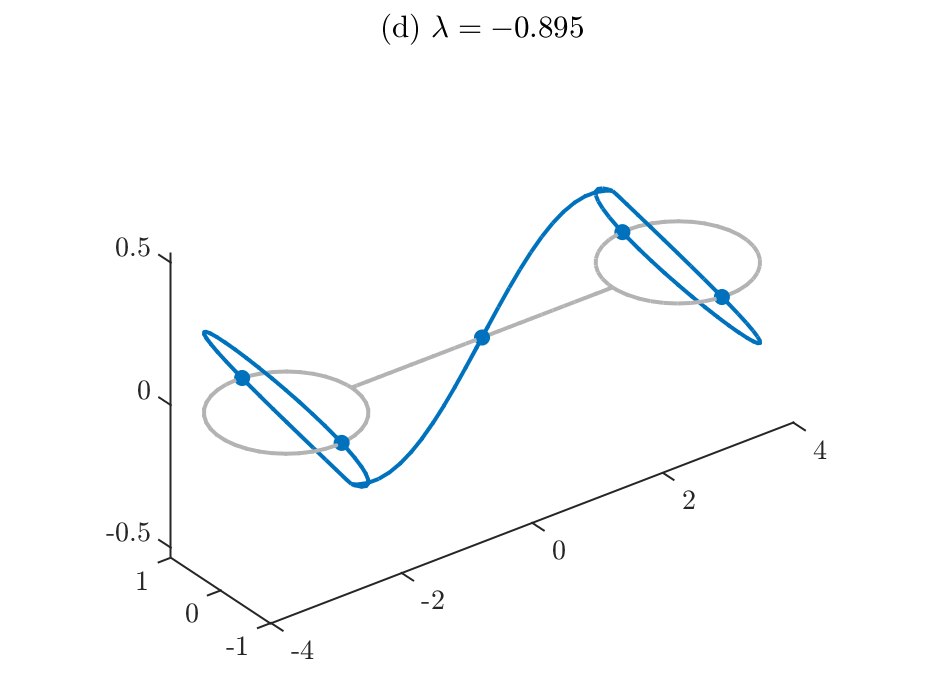

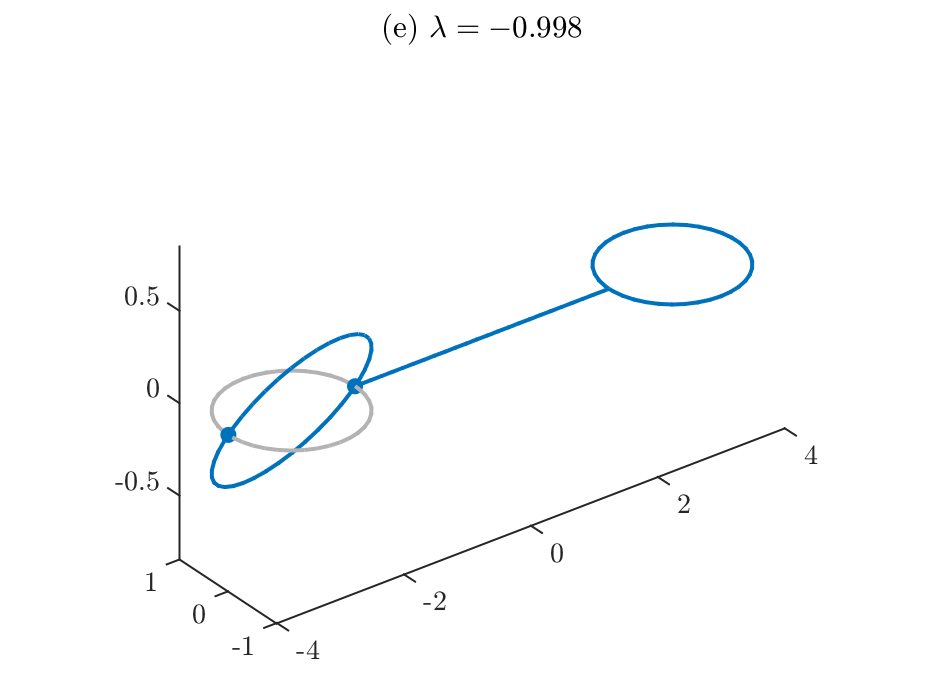

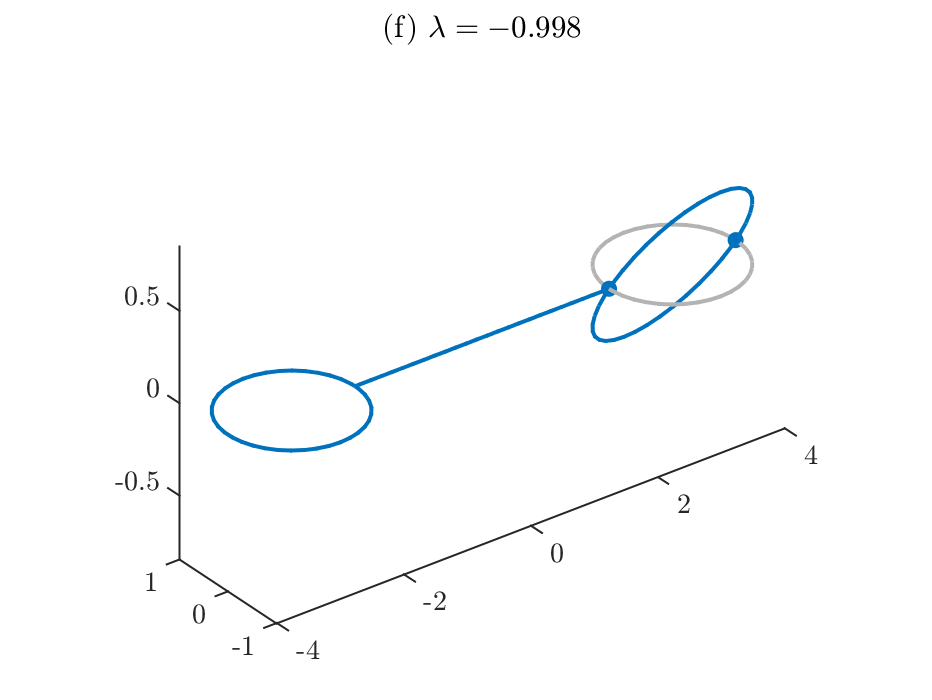

nToPlot=4;
nDoubles=1;
saveEigenfunctions(Phi,tag,dataDir,nToPlot,nDoubles);

#### Define the cubic nonlinearity and save it to the data directory. 

This must be a symbolic function of a single variable `z`. The default is $f(z)= 2z^3$, but we change this here to $f(z)=-2z^3 + 3 z^5$This function is  the default the argument `f` can be omitted.

syms z
f = -2*z^3+3*z^5;
fcns = saveNLSFunctionsGraph(dataDir,Phi,f);

## Compute branches that are continuation of the three least oscillatory eigenfunctions

- The function `continuerSet` acts like the MATLAB functions `odeset` and `optimset.` It sets a number of options that are used by the continuation programs

- The function `continueFromEig` continues a branch from the linear limit of an eigenfunction computed in the previous step

options=continuerSet([],'maxTheta',1,'LambdaThresh',-1,'NThresh',9,'plotFlag',false,'minNormDelta',1e-3);
branch1=continueFromEig(dataDir,1,options);

N threshold crossed.
Branch number 1.
Data saved to directory data/dumbbell/114/branch001.
Branching Bifurcation at solution number 16.
Branching Bifurcation at solution number 20.
Branching Bifurcation at solution number 24.
Branching Bifurcation at solution number 28.


options=continuerSet(options,'maxTheta',2);
branch2=continueFromEig(dataDir,2,options);

Lambda threshold crossed.
Branch number 2.
Data saved to directory data/dumbbell/114/branch002.
Branching Bifurcation at solution number 5.
Branching Bifurcation at solution number 14.


branch3=continueFromEig(dataDir,3,options);

Lambda threshold crossed.
Branch number 3.
Data saved to directory data/dumbbell/114/branch003.
No branching bifurcations found.


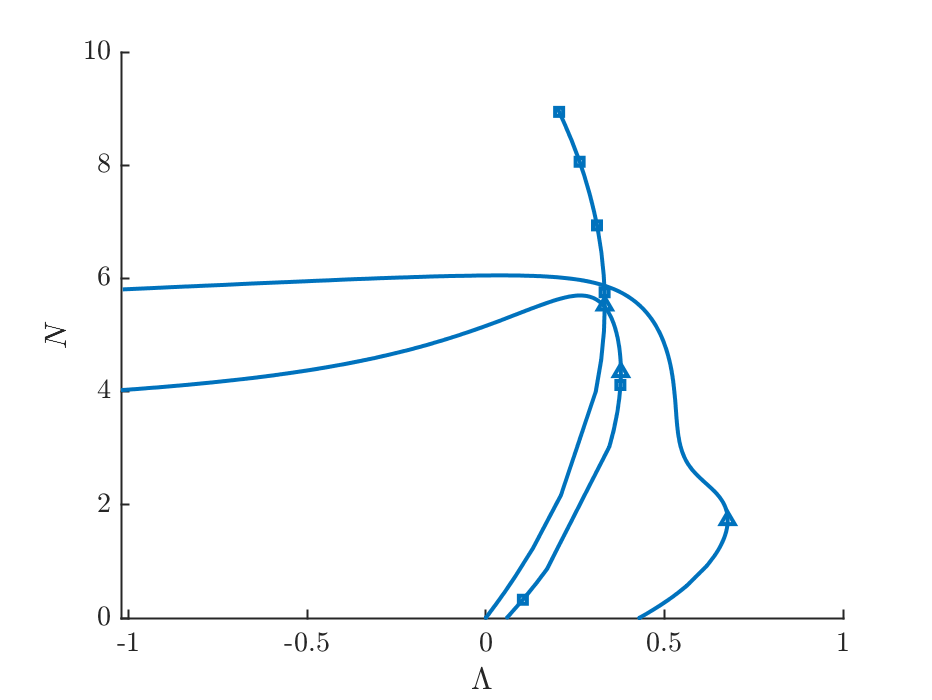

bifurcationDiagram(dataDir)

## Compute some branches that bifurcate from this first branch

- The function `continueFromBranchpoint` continues a branch from the first branching bifurcation point. Since this is a symmetry-breaking bfirucation, we only need to continue in one direction, the branch stored in branch`1` at bifurcation location 1 

location=1;
direction=1;
branch4=continueFromBranchPoint(dataDir,branch1,location,direction,options);

Lambda threshold crossed.
Branch number 4.
Data saved to directory data/dumbbell/114/branch004.
No branching bifurcations found.


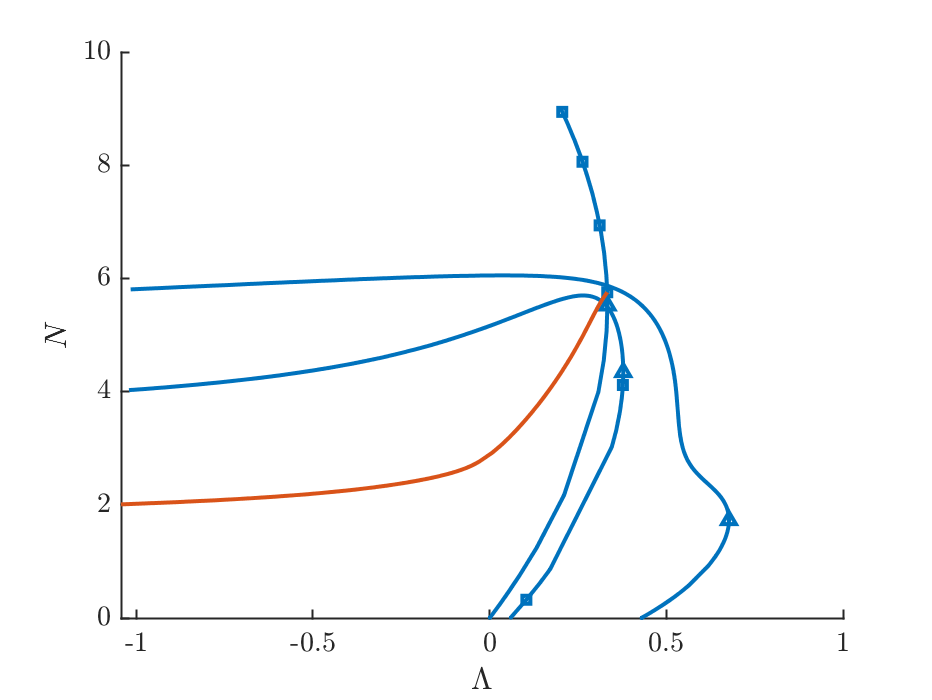

bifurcationDiagram(dataDir)

location=2;
direction=1;
branch5=continueFromBranchPoint(dataDir,branch1,location,direction,options);

Lambda threshold crossed.
Branch number 5.
Data saved to directory data/dumbbell/114/branch005.
Branching Bifurcation at solution number 22.


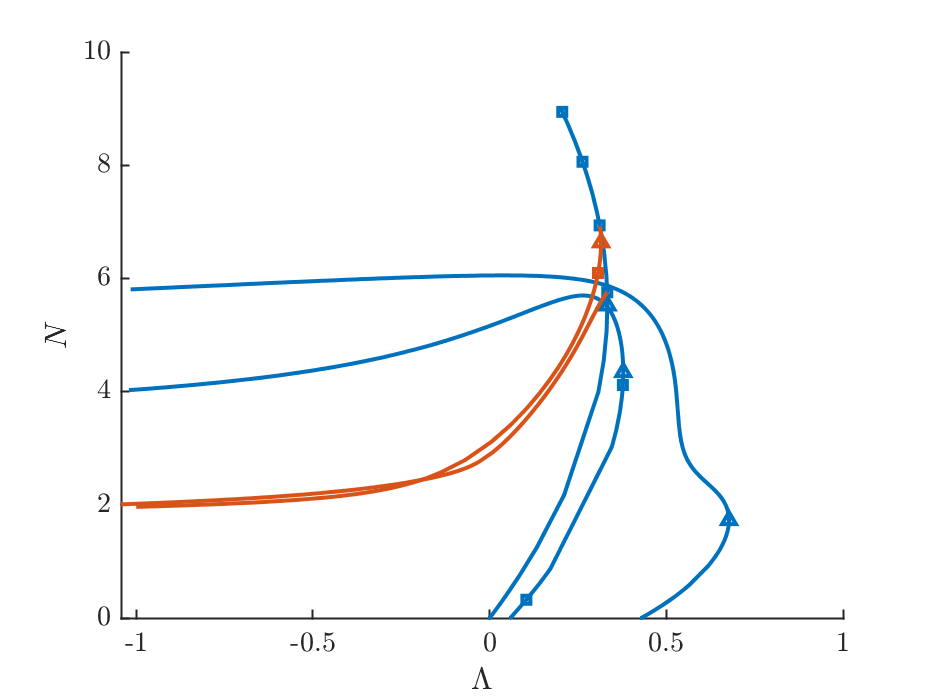

bifurcationDiagram(dataDir)

location=2;
direction=-1;
branch6=continueFromBranchPoint(dataDir,branch1,location,direction,options);

Lambda threshold crossed.
Branch number 6.
Data saved to directory data/dumbbell/114/branch006.
No branching bifurcations found.


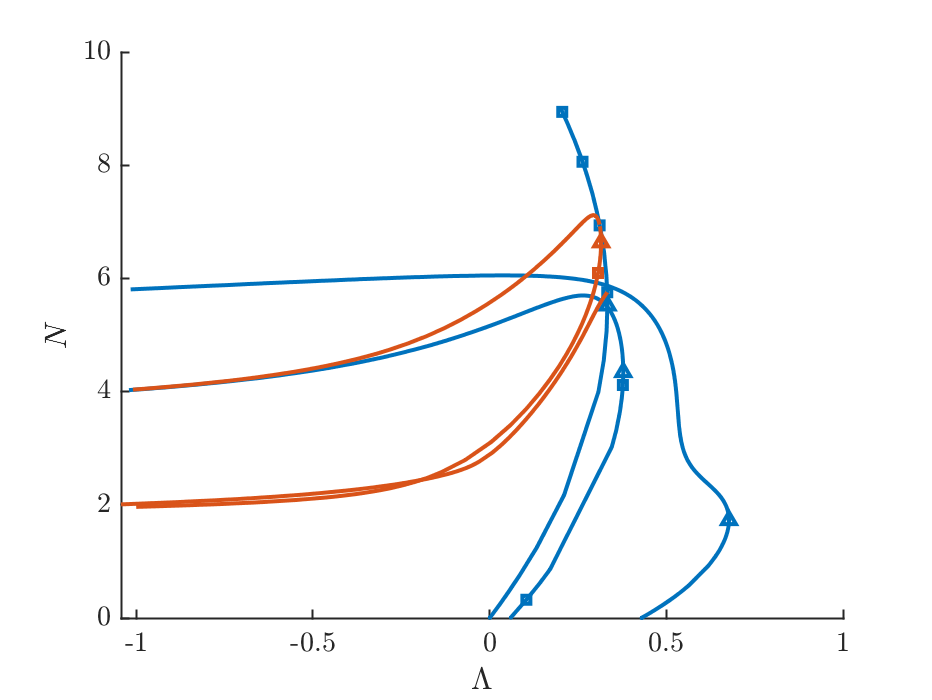

bifurcationDiagram(dataDir)

location=3;
direction=1;
branch7=continueFromBranchPoint(dataDir,branch1,location,direction,options);

Lambda threshold crossed.
Branch number 7.
Data saved to directory data/dumbbell/114/branch007.
No branching bifurcations found.


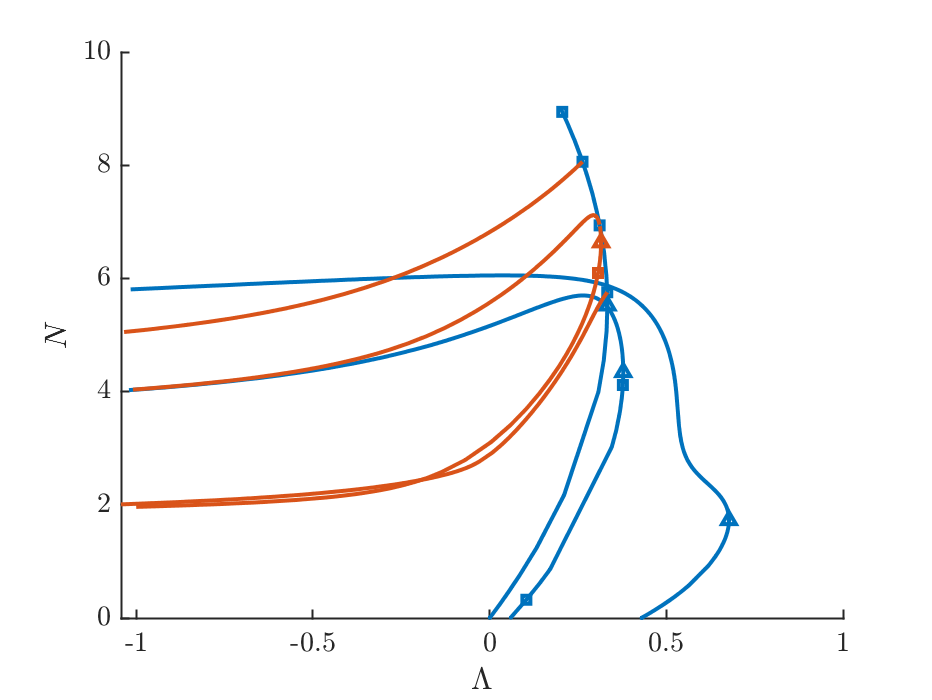

bifurcationDiagram(dataDir)

## Compute a branch that bifurcates from the second nonlinear eigenfunction branch

Continues from the branch stored in branch2 from the bifurcation point 1. Interestingly, the bifurcating branch intersects the "original" branch in two locations, each time in a symmetry-breaking bifurcation. Because of this, the branch is similar to an isola, and if we don't limit the number of points computed, it will just keep repeating. Therefore we set `maxPoints=210` which is enough to plot all the whole branch without much repetition.

location=1;
direction=1;
options=continuerSet(options,'maxPoints',210);
branch8=continueFromBranchPoint(dataDir,branch2,location,direction,options);

Maximum number of points on curve exceeded. Change maxPoints if needed.
Branch number 8.
Data saved to directory data/dumbbell/114/branch008.
No branching bifurcations found.


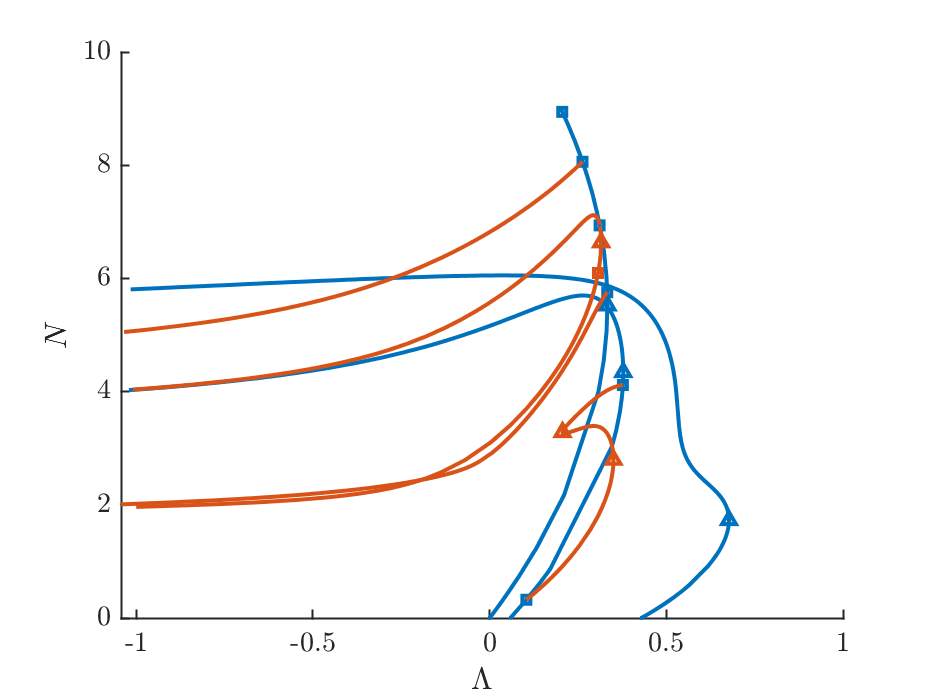

bifurcationDiagram(dataDir)